clear all
clear

## Initial postion of guide and scout

% create initial positon of guide, scout and  obstacles
L = 64;  % dimension of map
initPos =randi([1,L],3,2);
sGuide0 = [initPos(1,1) initPos(1,2)]; %  init guide location from random distribution
sScout0 =[initPos(2,1) initPos(2,2)];%  init scout location from random distribution
obstacleLoca = [ num2str(initPos(3,1))  num2str(initPos(3,2)) ]

obstacleLoca = '4154'

s0 = [sGuide0;sScout0];
% create Map
gridMap = createGridWorld(L,L,'Kings') 

gridMap =   GridWorld with properties:

          GridSize: [64 64]
      CurrentState: "[1,1]"
            States: [4096×1 string]
           Actions: [8×1 string]
                 T: [4096×4096×8 double]
                 R: [4096×4096×8 double]
    ObstacleStates: [0×1 string]
    TerminalStates: [0×1 string]


gridMap.TerminalStates = ['[' num2str(sGuide0(1,1)) ',' num2str(sGuide0(1,2)) ']' ]

gridMap =   GridWorld with properties:

          GridSize: [64 64]
      CurrentState: "[1,1]"
            States: [4096×1 string]
           Actions: [8×1 string]
                 T: [4096×4096×8 double]
                 R: [4096×4096×8 double]
    ObstacleStates: [0×1 string]
    TerminalStates: "[26,52]"


gridMap.ObstacleStates = ['[' num2str(initPos(3,1)) ',' num2str(initPos(3,2)) ']' ]

gridMap =   GridWorld with properties:

          GridSize: [64 64]
      CurrentState: "[1,1]"
            States: [4096×1 string]
           Actions: [8×1 string]
                 T: [4096×4096×8 double]
                 R: [4096×4096×8 double]
    ObstacleStates: "[41,54]"
    TerminalStates: "[26,52]"


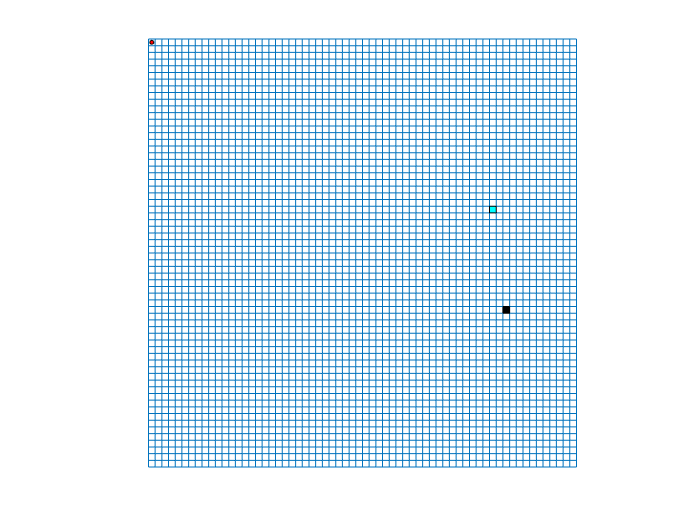

env = rlMDPEnv(gridMap);
% Reset Function 
env.ResetFcn = @(in) resetFcn(in,obstacleLoca);
% Draw Map 
plot(env)

Hypeparameters

episode = 1; % initial training episodes
episodeMax = 5e5;% max training episodes
Ts = 0.1;
Tf = 100;
maxsteps = ceil(Tf/Ts);

## Action space & Observation space

#### observation 1 and action 1 (Guide)

% obs info
obs1Size = [L L 3];
obs1Info = rlNumericSpec(obs1Size);
obs1Info.Name = "Observation";
obs1Info.Description = "guide x location, guide y location,  scout x location, scout y locaton";

% act info
act1Info = getActionInfo(env);

#### reward  function

## Build Agent for Guide

% random number generator
rng(0)

Choose Type of RL Agents

RLAgentType = inputdlg("Guide/ Agent 1 Reinforcement Learning Type (PPO/DQN/DDPG/RL/ACAgent): ", "Choices",[1 50])

RLAgentType = 1×1 cell array
    {'PPO'}


RLAgentType = cell2mat(RLAgentType);
  switch RLAgentType

Create PPO Agent

      case "PPO"    
 actorNetWork1 = [
        imageInputLayer(obs1Size,'Normalization','none','Name','observations')
        convolution2dLayer(8,16,'Name','conv1','Stride',1,'Padding',1,'WeightsInitializer','he')
        reluLayer('Name','relu1')
        convolution2dLayer(4,8,'Name','conv2','Stride',1,'Padding','same','WeightsInitializer','he')
        reluLayer('Name','relu2')
        fullyConnectedLayer(64,'Name','fc1','WeightsInitializer','he')
        reluLayer('Name','relu3')
        fullyConnectedLayer(64,'Name','fc2','WeightsInitializer','he')
        reluLayer('Name','relu4')
        fullyConnectedLayer(64,'Name','fc3','WeightsInitializer','he')
        reluLayer('Name','relu5')
        fullyConnectedLayer(length(act1Info.Elements),'Name','output')
        softmaxLayer('Name','action')];
    actorNetWork1 = dlnetwork(actorNetWork1);
    
    % Create critic deep neural network.
  criticNetwork1 = [
        imageInputLayer(obs1Size,'Normalization','none','Name','observations')
        convolution2dLayer(8,16,'Name','conv1','Stride',1,'Padding',1,'WeightsInitializer','he')
        reluLayer('Name','relu1')
        convolution2dLayer(4,8,'Name','conv2','Stride',1,'Padding','same','WeightsInitializer','he')
        reluLayer('Name','relu2')
        fullyConnectedLayer(256,'Name','fc1','WeightsInitializer','he')
        reluLayer('Name','relu3')
        fullyConnectedLayer(128,'Name','fc2','WeightsInitializer','he')
        reluLayer('Name','relu4')
        fullyConnectedLayer(64,'Name','fc3','WeightsInitializer','he')
        reluLayer('Name','relu5')
        fullyConnectedLayer(1,'Name','output')];
    criticNetwork1 = dlnetwork(criticNetwork1); 

actor1 = rlDiscreteCategoricalActor(actorNetWork1,obs1Info,act1Info); %#ok<*SAGROW> 
    critic1 = rlValueFunction(criticNetwork1,obs1Info);

    actorOpts = rlOptimizerOptions('LearnRate',1e-4,'GradientThreshold',1);
    criticOpts = rlOptimizerOptions('LearnRate',1e-4,'GradientThreshold',1); 

    opt = rlPPOAgentOptions(...
    'ActorOptimizerOptions',actorOpts,...
    'CriticOptimizerOptions',criticOpts,...
    'ExperienceHorizon',128,...
    'ClipFactor',0.2,...
    'EntropyLossWeight',0.01,...
    'MiniBatchSize',64,...
    'NumEpoch',3,...
    'AdvantageEstimateMethod','gae',...
    'GAEFactor',0.95,...
    'SampleTime',Ts,...
    'DiscountFactor',0.995);


    agent1 = rlPPOAgent(actor1,critic1,opt);


  end
